clear; close all; clc; format compact;

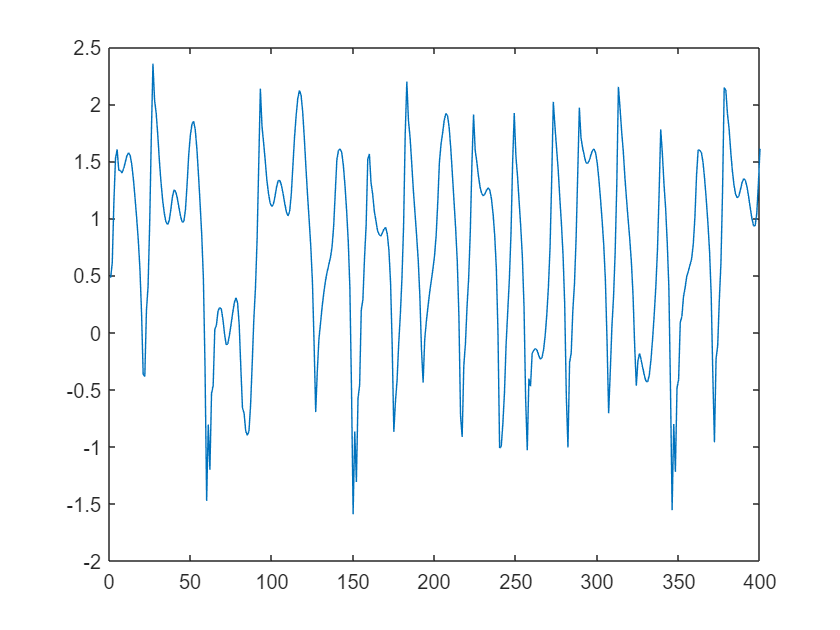

N = 400;

k = 1:N;
desired_origin = d(N);
inputs_origin = x(N);

figure
plot(k, desired_origin);

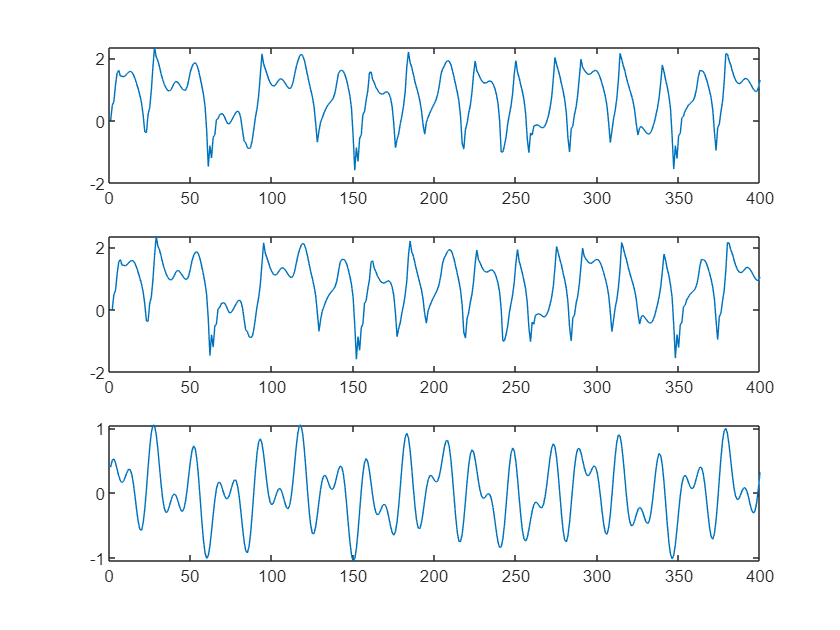


figure;
subplot(3,1,1);
plot(k, inputs_origin(1,:));
subplot(3,1,2);
plot(k, inputs_origin(2,:));
subplot(3,1,3);
plot(k, inputs_origin(3,:));

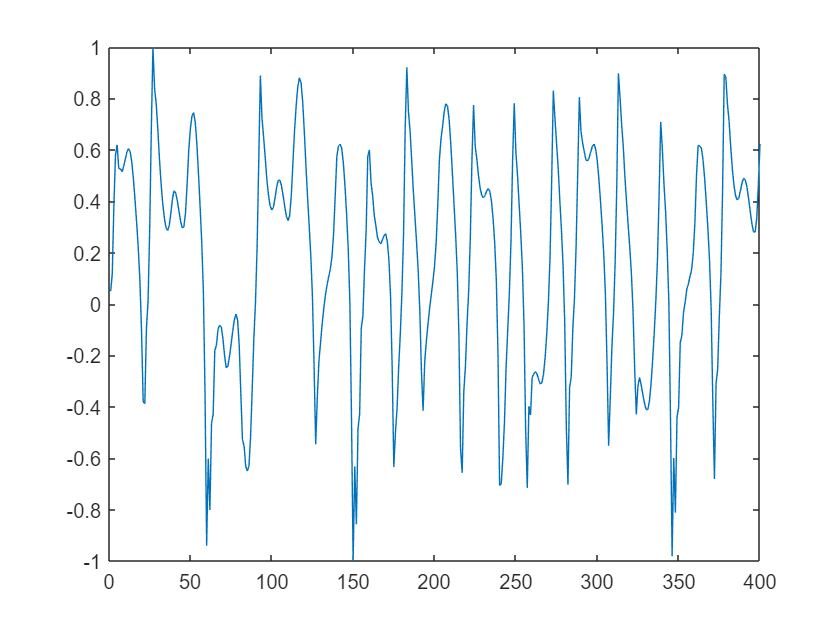

% offset the desired outputs between sigmoidal bound
max_d = max(desired_origin);
min_d = min(desired_origin);
width = max_d - min_d;
offset = (max_d + min_d) / 2;
desired_norm = 2 * (desired_origin - offset) / width;

figure
plot(k, desired_norm);

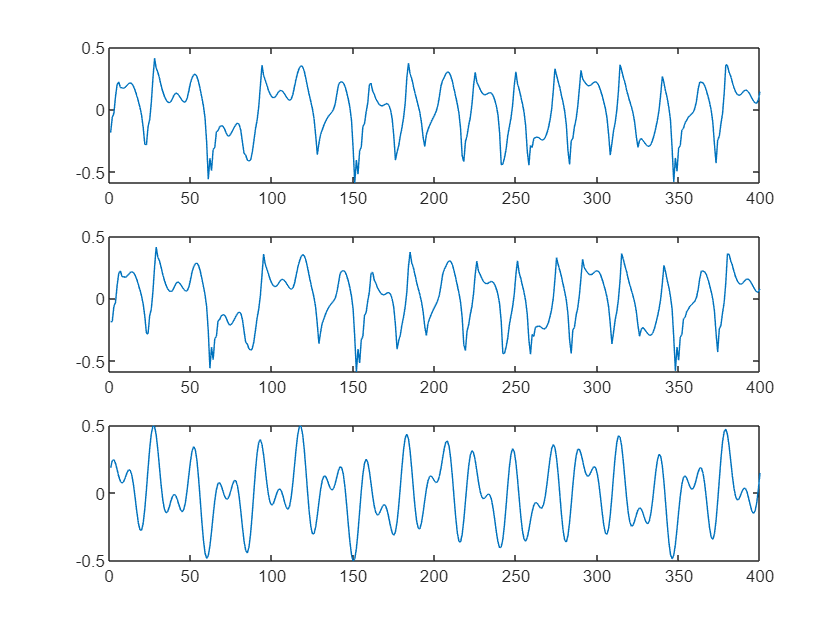

% mean removal preprocess on the input data
inputs_norm = inputs_origin;
mean_inputs = [mean(inputs_norm(1,:)); mean(inputs_norm(2,:)); mean(inputs_norm(3,:))];
inputs_norm = inputs_norm - mean_inputs;

max_inputs = [max(inputs_norm(1,:)); max(inputs_norm(2,:)); max(inputs_norm(3,:))];
min_inputs = [min(inputs_norm(1,:)); min(inputs_norm(2,:)); min(inputs_norm(3,:))];
width_inputs = max_inputs - min_inputs;

inputs_norm = inputs_norm ./ width_inputs;

figure;
subplot(3,1,1);
plot(k, inputs_norm(1,:));
subplot(3,1,2);
plot(k, inputs_norm(2,:));
subplot(3,1,3);
plot(k, inputs_norm(3,:));

% shuffling the data presented to the network
% inputs_random = zeros(size(inputs_norm));
% desired_random = zeros(size(desired_norm));
% 
% j = 0;
% index_shuffle = randperm(N);
% for i = index_shuffle
%     j = j + 1;
%     inputs_random(:, j) = inputs_norm(:, i);
%     desired_random(j) = desired_norm(i);
% end
% 
% figure
% plot(k, desired_random);
% 
% figure;
% subplot(3,1,1);
% plot(k, inputs_random(1,:));
% subplot(3,1,2);
% plot(k, inputs_random(2,:));
% subplot(3,1,3);
% plot(k, inputs_random(3,:));

dimIn = 3;          % number of inputs exc. bias
dimOut = 1;         % number of outputs
dimHidden = [15];    % dimensions of each hidden layer ex. bias

nHiddenLayers = size(dimHidden, 2);

N = 400;
trainRatio = 0.6;
validRatio = 0.2;
testRatio = 0.2;

nTrain = uint16(N * trainRatio);
nValid = uint16(N * validRatio);
nTest = uint16(N * testRatio);

maxEpoch = 500;     % maximum number of iterations
eta = 0.25;
alpha = 0.0;

% adding +1 row for including synaptic threshold
xi = ones([size(inputs_norm, 1)+1, nTrain]);
xi(2:end, :) = inputs_norm(:, 1:nTrain)

xi =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -0.1863   -0.0646   -0.0314    0.1033    0.2002    0.2203    0.1738    0.1736    0.1677    0.1781    0.1917    0.2061    0.2127    0.2068    0.1865    0.1535    0.1127    0.0679    0.0183   -0.0450   -0.1434   -0.2796   -0.2837   -0.1377   -0.0839    0.0558    0.2499    0.4104    0.3296    0.3000    0.2507    0.1926    0.1451    0.1065    0.0779    0.0592    0.0533    0.0626    0.0869    0.1156    0.1308    0.1264    0.1111    0.0908    0.0715    0.0586    0.0604    0.0872    0.1441    

dk = desired_norm(1:nTrain)

dk =     0.0500    0.1163    0.3858    0.5796    0.6197    0.5267    0.5264    0.5145    0.5353    0.5626    0.5914    0.6045    0.5928    0.5522    0.4862    0.4045    0.3150    0.2158    0.0891   -0.1076   -0.3801   -0.3882   -0.0963    0.0114    0.2907    0.6790    1.0000    0.8383    0.7792    0.6806    0.5644    0.4693    0.3922    0.3350    0.2976    0.2857    0.3043    0.3529    0.4104    0.4407    0.4320    0.4013    0.3608    0.3221    0.2964    0.2999    0.3536    0.4673    0.5979    0.6825


% weight initialization
m = [dimIn, (dimIn+dimOut)*dimHidden(1)];
stand_dev = m.^(-1/2);

wji = zeros([dimHidden(1), (dimIn+1)]);
wkj = zeros([dimOut, (dimHidden(1)+1)]);

wji(:, 2:end) = normrnd(0, stand_dev(1)^2, [dimHidden(1), dimIn])

wji =          0    0.1792   -0.0683    0.2961
         0    0.6113   -0.0414   -0.3824
         0   -0.7529    0.4966   -0.3563
         0    0.2874    0.4697   -0.2698
         0    0.1063    0.4724   -0.9814
         0   -0.4359    0.2238    0.4795
         0   -0.1445   -0.4025    0.1084
         0    0.1142    0.2391   -0.2516
         0    1.1928    0.5434    0.4568
         0    0.9231    0.1630   -0.5705


wkj(:, 2:end) = normrnd(0, stand_dev(2)^2, [dimOut, dimHidden(1)])

wkj =          0   -0.0005   -0.0027    0.0105    0.0182    0.0185   -0.0144    0.0013   -0.0202   -0.0186   -0.0001    0.0255   -0.0128    0.0062   -0.0038    0.0186


 
vj = zeros([dimHidden(1), 1]);
yj = zeros([(dimHidden(1)+1), 1]);
yj(1, :) = 1;

vk = zeros([dimOut, 1]);
yk = zeros([dimOut, nTrain]);

ek = -1 * ones(size(dk));   % instantaneous error signal
E = (1/2) * ek.^2;          % total instantaneous error energy
MSE = zeros([1, maxEpoch]);

delta_k = 0;    % local gradient for the output neuron
delta_j = 0;    % local gradient for the hidden layer

delta_wji = zeros(size(wji));
delta_wkj = zeros(size(wkj));

xvalid = ones([size(inputs_norm, 1)+1, nValid]);
xvalid(2:end, :) = inputs_norm(:, nTrain+1:nTrain+nValid);
dvalid = desired_norm(nTrain+1:nTrain+nValid);

yvalid = zeros([dimOut, nValid]);

ek_valid = -1 * ones(size(dvalid));   % instantaneous error signal
E_valid = (1/2) * ek_valid.^2;        % total instantaneous error energy
MSE_valid = zeros([1, maxEpoch]);

% MLP
for epoch = 1:maxEpoch
    for n = 1:nTrain
        % feed forward phase
        vj = wji * xi(:,n);
        yj(2:end) = phi(vj);
    
        vk = wkj * yj;
        yk(n) = phi(vk);

        % back-propagation algorithm
        ek(n) = dk(n) - yk(n);
        E(n) = (1/2) * ek(n)^2;
    
        delta_k = ek(n) * phi_derivative(yk(n));
        delta_j = delta_k * wkj(2:end)' .* phi_derivative(yj(2:end));

        delta_wji = (alpha * delta_wji) + (eta * delta_j * xi(:, n)');
        wji = wji + delta_wji;

        delta_wkj = (alpha * delta_wkj) + (eta * delta_k * yj');
        wkj = wkj + delta_wkj;
    end

    % cross validation
    for n = 1:nValid
        vj = wji * xvalid(:, n);
        yj(2:end) = phi(vj);
    
        vk = wkj * yj;
        yvalid(n) = phi(vk);

        ek_valid(n) = dvalid(n) - yvalid(n);
        E_valid(n) = (1/2) * ek_valid(n)^2;
    end    

    MSE(epoch) = sum(E)/numel(E);
    MSE_valid(epoch) = sum(E_valid)/numel(E_valid);
end

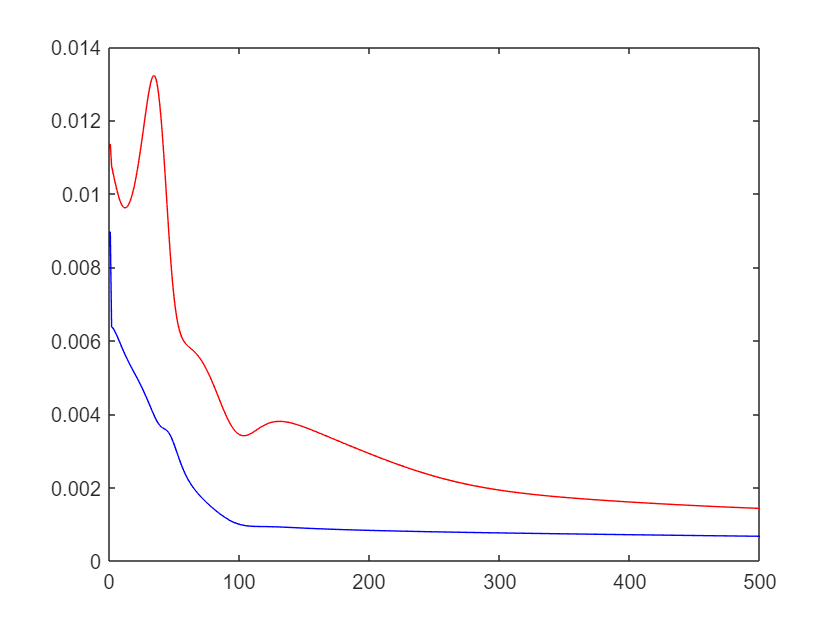

% figure;
% plot(k, E);
figure;
plot(1:maxEpoch, MSE, 'b');
hold on;
plot(1:maxEpoch, MSE_valid, 'r');

wkj

wkj =     0.2355   -0.0276   -0.0664    0.1063   -0.0244   -0.0573    0.0487    0.0015   -0.0031    0.5132   -0.5636    0.0635   -0.1044   -0.0331    0.0035   -0.0302


wji

wji =     0.0618    0.1343    0.0418   -0.0198
   -0.0353    0.7245   -0.1067   -0.6079
   -0.1442   -0.8130    0.3051    0.1405
   -0.1128    0.2716    0.3746   -0.7661
   -0.2211    0.2549    0.1577   -0.7555
    0.0279   -0.5967    0.3100    0.3155
    0.0581   -0.0753   -0.3293    0.4556
   -0.0604    0.1211    0.1409   -0.3452
    0.3771    5.4526    4.5608   -0.8933
    0.4688    2.6443    0.9861   -2.6100


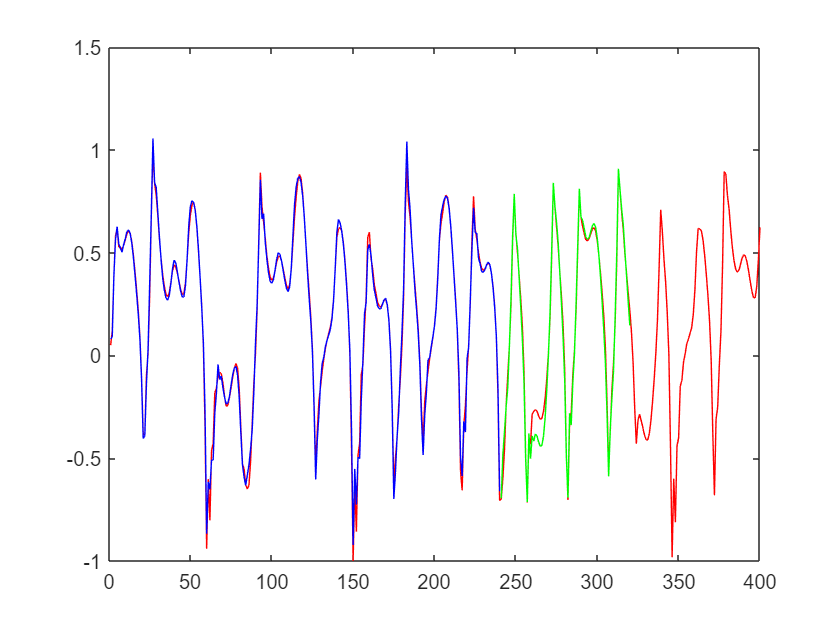


figure;
plot(k, desired_norm, 'r');
hold on
plot(1:nTrain, yk, 'b')
hold on;
plot(nTrain+1:nTrain+nValid, yvalid, 'g')

xtest = ones([size(inputs_norm, 1)+1, nTest]);
xtest(2:end, :) = inputs_norm(:, nTrain+nValid+1:nTrain+nValid+nTest);
dtest = desired_norm(nTrain+nValid+1:nTrain+nValid+nTest);

ytest = zeros([dimOut, nTest]);

% MLP test
for n = 1:nTest
    vj = wji * xtest(:, n);
    yj(2:end) = phi(vj);

    vk = wkj * yj;
    ytest(n) = phi(vk);
end


ek_test = dtest - ytest;
E_test = (1/2) * ek_test(n).^2;
MSE_test = sum(E_test)/numel(E_test)

MSE_test = 4.5112e-04

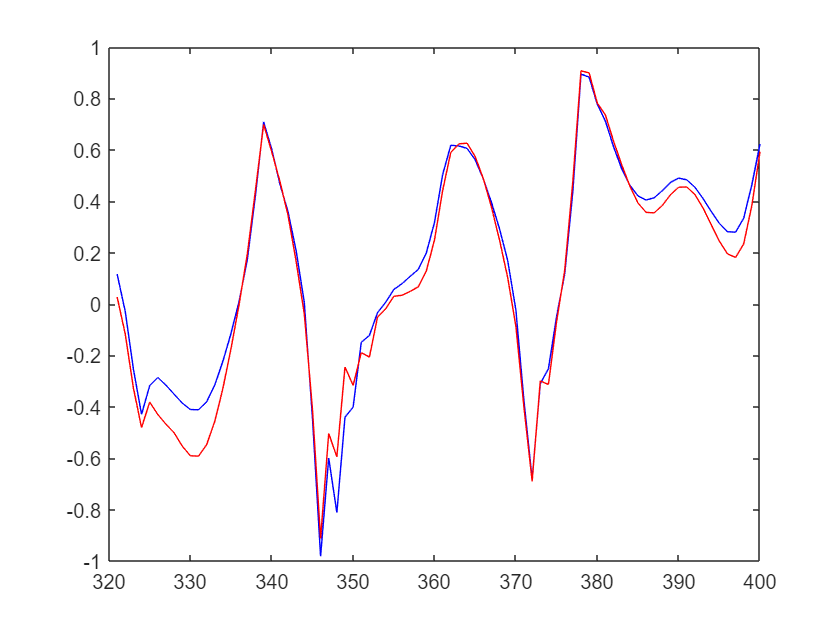

figure;
plot(nTrain+nValid+1:nTrain+nValid+nTest, dtest, 'b');
hold on;
plot(nTrain+nValid+1:nTrain+nValid+nTest, ytest, 'r');

### **Functions**

function [control_sig] = u(k)
    control_sig = 0.5*sin(k*(pi/11)) + 0.4*cos(k*(pi/6.5)) + 0.2*sin(k*(pi/45));
end

function [desired_vec] = d(N)
    alpha = 1.2;
    beta = 1.1;

    if N <= 1
        N = 1;
    elseif N >= 400
        N = 400;
    end

    desired_vec = zeros([1, N]);
    for k = 1:N
        if k < 3
            desired_vec(k) = alpha * u(k-1);
        else
            desired_vec(k) = alpha * ((desired_vec(k-1)*desired_vec(k-2)*(desired_vec(k-2) + beta)) / (1 + ((desired_vec(k-1)^2)*(desired_vec(k-2)^2))) + u(k-1));
        end
    end
end

function [input_vec] = x(N)
    if N <= 1
        N = 1;
    elseif N >= 400
        N = 400;
    end

    input_vec = zeros([3, N]);
    desired_vec = d(N);

    for k = 1:N
        if k == 1
            input_vec(:, k) = [    0,    0,  u(k-1)]';
        elseif k == 2
            input_vec(:, k) = [ desired_vec(1),    0,  u(k-1)]';
        else
            input_vec(:, k) = [ desired_vec(k-1),  desired_vec(k-2), u(k-1)]';
        end
    end
end

function [activation] = phi(v)
    a = 1.7159;
    b = 2/3;
    activation = a*tanh(b*v);
end

function [derivative] = phi_derivative(y)
    a = 1.7159;
    b = 2/3;
    derivative = (b/a)*(a - y).*(a + y);
end